# Chapitre 1: Décompositions matricielles

## 1.1 Décomposition en valeurs singulières

Charger une image monochromatique dans Matlab:

X = double(imread('cameraman.tif'));
X = X(:,1:220);
[n,m] = size(X);

Pour cette matrice:

- Visualiser les données à l'aide de la fonction `imagesc. `Utiliser `colorbar` pour montrer la gamme de couleurs. Choisir la gamme "niveaux de gris" (`'gray'`) avec la fonction `colormap.`

% Insérer le code ici

- Calculer la SVD de $X \in \mathbb{R}^{n\times m}$ à l'aide de la fonction `svd`. Tracer la courbe de valeurs singulières avec la fonction `plot`.

% Insérer le code ici

- Calculer les valeurs propres de la matrice $X^\top X$ (fonction `eig`). Vérifier que les valeurs propres sont les carrés des valeurs singulères $\sigma_k$ de $X$.

## 1.2 Approximations de faible rang

On se donne un entier $r \leq \mathrm{rang}(X)$.

r = 73;

On définit les sous-matrices $U_r$, $S_r$ et $V_r$ à partir des facteurs $U$, $S$ et $V$ de la SVD.

Ur = U(:,1:r);

Unrecognized function or variable 'U'.

Sr = S(1:r,1:r);
Vr = V(:,1:r);

- Pour $r < \min(n,m)$, les matrices extraites $U_r \in \mathbb{R}^{n\times r}$  et $V_r \in \mathbb{R}^{m\times r}$ ne sont plus orthonormales. Lesquelles de ces égalités sont fausses: 1) $U_r U_r^\top = I_n$?     2) $U_r^\top U_r = I_r$?     3) $V_r V_r^\top = I_m$ ?    4)$V_r^\top V_r = I_r$?

% Insérer le code ici

- Pour quelques valeurs de $r$ ($r=2,5,20,80$), calculer la meilleure approximation de rang $r$, donnée par la formule $X_r = U_rS_rV_r^\top$ (SVD "tronquée"). Pour chaque $r$, afficher l'approximation avec `imagesc`. Que se passe-t-il lorsqu'on augmente le rang de l'approximation?

r_list = [2,5,20,80];
% Insérer le code ici
for r = r_list
    % Insérer le code ici
end

- Compléter le code précédent pour calculer en plus pour chaque $r$ l'erreur d'approximation $\epsilon_r = \vert\!\vert X - X_r \vert\!\vert_F$ où $\vert\!\vert \cdot \vert\!\vert_F$ est la norme de Froebenius (utiliser la commande `norm(M,'fro')` pour calculer la norme de Froebenius d'une matrice $M$). Tracer (avec `plot`) les valeurs d'erreur obtenues.

- Calculer les valeurs $\delta_r  = \sqrt{\sum_{k=r+1}^{\min(n,m)} \sigma_k^2$ pour chaque $r$, où les $\sigma_k$ sont les valeurs singulières de $X$, puis comparer (en utilisant `plot`) avec les $\epsilon_r$ obtenus à la question précédente. 

sigma = diag(S); % vecteur des valeurs singulières
% Insérer le code ici
for r = r_list
    % Insérer le code ici
end

# Chapitre 2: Décompositions tensorielles

Les données pour le TD sont stockées dans le fichier `td_tenseurs.mat` (elles peuvent être chargées avec `load`). Pour cet excercice, il faut utiliser la N-way Toolbox qui peut être trouvée dans le fichier nway331.zip. Il est préférable de mettre la toolbox dans un dossier séparé (par exemple nway) et utiliser `addpath`.

addpath('nway');
load('td_tenseurs.mat');

## 2.1 Données de spectroscopie

Les variables $A,B,C$ stokées dans `td_tenseurs.mat sont:`

$A = [a_1 \; \ldots \;\; a_R ] \in \mathbb{R}^{I\times R}$, $B = [b_1 \; \ldots \;\; b_R ] \in \mathbb{R}^{J\times R}$, $C = [c_1 \; \ldots \;\; c_R ] \in \mathbb{R}^{K\times R}$.

Ce sont des données de spectroscopie de fluorescence (mélange de $R$ composants, $a_k$ — concentrations; $c_k$ — spectres d’absorption ; $b_k$ — spectres d’émission).

Par défault, la commande `plot` trace chaque colonne d'une matrice.

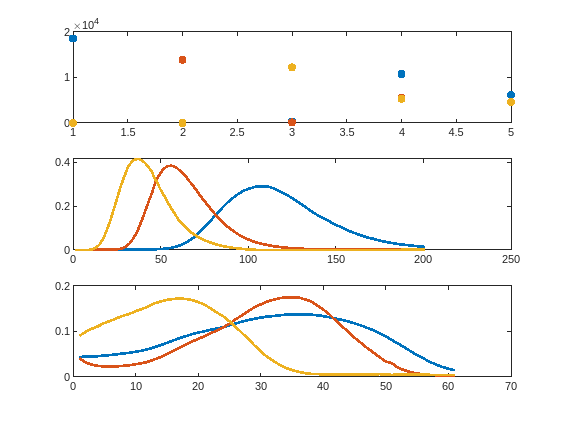

I = size(A,1);
J = size(B,1);
K = size(C,1);
R = size(A,2);

subplot(3,1,1), plot(A,'.','linewidth',2,'markersize',15);

subplot(3,1,2), plot(B,'linewidth',2);
subplot(3,1,3), plot(C,'linewidth',2);

- Tracer

- Construire le tenseur $\mathcal{T} \in \mathbb{R}^{I\times J\times K}$ comme $\mathcal{T} = \sum_{r=1}^R a_r \circ b_r \circ c_r$. Pour calculer le produit extérieur $\circ$, il faut utiliser la fonction `outerprod` fournie.

T = zeros(I,J,K);
% Insérer le code ici

- Sélectionner la tranche horizontale $Z = \mathcal{T}_{3,\,:\,,\,:}$. Afficher la tranche avec `imagesc`.

% Insérer le code ici